# Konspekt 1

%przypisanie dowolnych wartosci z przedzialu <1, 10>
k = 2;
T = 3;
T1 = 4;
T2 = 5;
ksi = 1.5;
Ti = 6;
Td = 7;
Theta = 3;
t = 0: 0.1: 20;


%Zapisanie transmitancji obiektu:
inercyjny_I = tf([0,k], [T,1])

inercyjny_I =
 
     2
  -------
  3 s + 1
 
Continuous-time transfer function.



inercyjny_II = tf([0,0,k], [T1*T2 ,T1+T2 ,1])

inercyjny_II =
 
         2
  ----------------
  20 s^2 + 9 s + 1
 
Continuous-time transfer function.



inercyjny_II_inny = tf([0,0,k], [T^2 ,2*ksi*T ,1])

inercyjny_II_inny =
 
         2
  ---------------
  9 s^2 + 9 s + 1
 
Continuous-time transfer function.



calkujacy_r = tf([0,0,k], [T*Ti , Ti , 0])

calkujacy_r =
 
       2
  ------------
  18 s^2 + 6 s
 
Continuous-time transfer function.



rozniczkujacy_r = tf([Td,0], [T,1])

rozniczkujacy_r =
 
    7 s
  -------
  3 s + 1
 
Continuous-time transfer function.



test = tf([0, 1], [1, 3, 2, 3])

test =
 
            1
  ---------------------
  s^3 + 3 s^2 + 2 s + 3
 
Continuous-time transfer function.



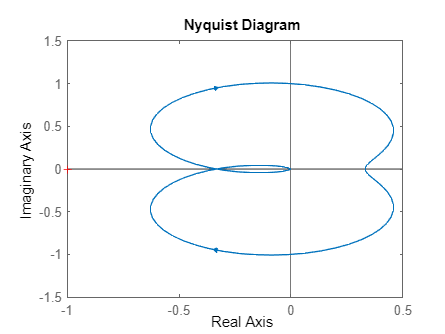

nyquist(test)

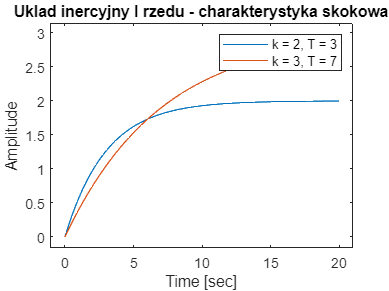


%Inercyjny I rzedu
y1 = step(inercyjny_I, t);
y1_i = impulse(inercyjny_I, t);

k_b = 3;
T_b = 7;      %zmiana zestawu danych

inercyjny_I_b = tf([0,k_b], [T_b,1]);
y1_b = step(inercyjny_I_b, t);
y1_i_b = impulse(inercyjny_I_b, t);


%Charakterystyki
figure
plot(t, y1, t, y1_b)
title('Uklad inercyjny I rzedu - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3', 'k = 3, T = 7')

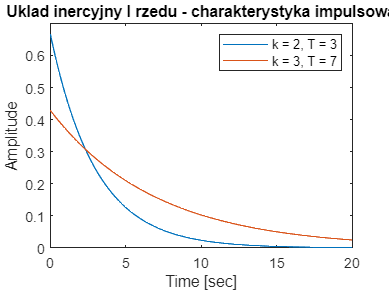

plot(t, y1_i, t, y1_i_b)
title('Uklad inercyjny I rzedu - charakterystyka impulsowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3', 'k = 3, T = 7')

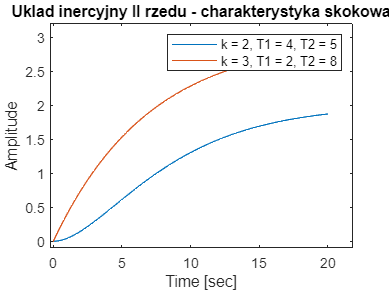


%Inercyjny II rzedu
y2 = step(inercyjny_II, t);
y2_i = impulse(inercyjny_II, t);

T1_b = 2;
T2_b = 8;

inercyjny_II_b = tf([0,0,k_b], [T1_b*T2_b ,T1_b+T2_b ,1]);
y2_b = step(inercyjny_I_b, t);
y2_i_b = impulse(inercyjny_I_b, t);


figure
plot(t, y2, t, y2_b)
title('Uklad inercyjny II rzedu - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T1 = 4, T2 = 5', 'k = 3, T1 = 2, T2 = 8')

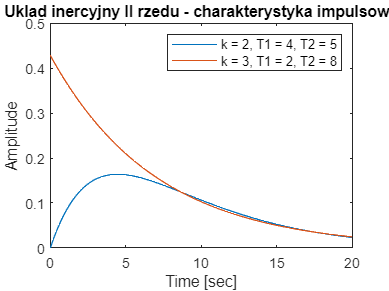

plot(t, y2_i, t, y2_i_b)
title('Uklad inercyjny II rzedu - charakterystyka impulsowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T1 = 4, T2 = 5', 'k = 3, T1 = 2, T2 = 8')

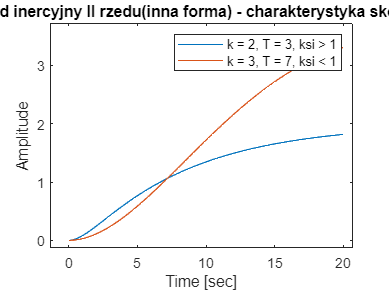


%Inercyjny II rzedu - inna forma
y3 = step(inercyjny_II_inny, t);
y3_i = impulse(inercyjny_II_inny, t);

ksi_b = 0.5;

inercyjny_II_inny_b = tf([0,0,k_b], [T_b^2 ,2*ksi_b*T_b ,1]);
y3_b = step(inercyjny_II_inny_b, t);
y3_i_b = impulse(inercyjny_II_inny_b, t);

figure
plot(t, y3, t, y3_b)
title('Uklad inercyjny II rzedu(inna forma) - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')

legend('k = 2, T = 3, ksi > 1', 'k = 3, T = 7, ksi < 1')

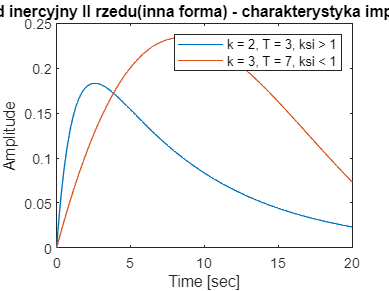

plot(t, y3_i, t, y3_i_b)
title('Uklad inercyjny II rzedu(inna forma) - charakterystyka impulsowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3, ksi > 1', 'k = 3, T = 7, ksi < 1')


% Calkujacy rzeczywisty
y4 = step(calkujacy_r, t);
y4_i = impulse(calkujacy_r, t);

Ti_b = 3;

calkujacy_r_b = tf([0,0,k_b], [T_b*Ti_b , Ti_b , 0]);
y4_b = step(calkujacy_r_b, t);
y4_i_b = impulse(calkujacy_r_b, t);

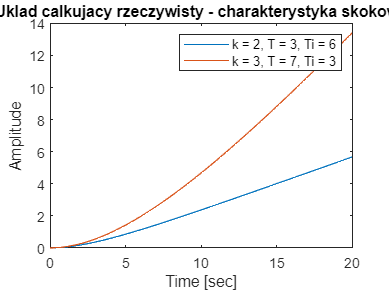


figure
plot(t, y4, t, y4_b)
title('Uklad calkujacy rzeczywisty - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3, Ti = 6', 'k = 3, T = 7, Ti = 3')

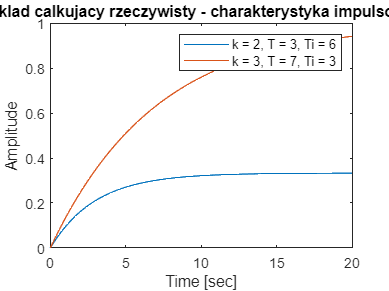

plot(t, y4_i, t, y4_i_b)
xlabel('Time [sec]')
ylabel('Amplitude')
title('Uklad calkujacy rzeczywisty - charakterystyka impulsowa')
legend('k = 2, T = 3, Ti = 6', 'k = 3, T = 7, Ti = 3')

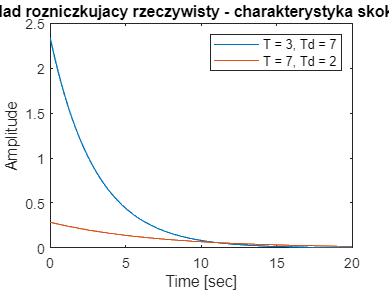


%Rozniczkujacy rzeczywisty
y5 = step(rozniczkujacy_r, t);
y5_i = impulse(rozniczkujacy_r, t);

Td_b = 2;

rozniczkujacy_r_b = tf([Td_b,0], [T_b,1]);
y5_b = step(rozniczkujacy_r_b, t);
y5_i_b = impulse(rozniczkujacy_r_b, t);

figure
plot(t, y5, t, y5_b)
title('Uklad rozniczkujacy rzeczywisty - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('T = 3, Td = 7', 'T = 7, Td = 2')

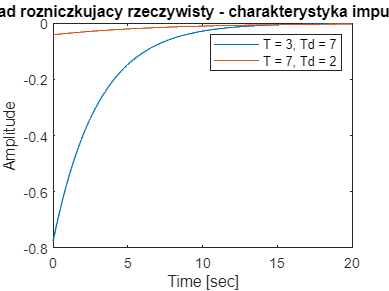

plot(t, y5_i, t, y5_i_b)
title('Uklad rozniczkujacy rzeczywisty - charakterystyka impulsowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('T = 3, Td = 7', 'T = 7, Td = 2')

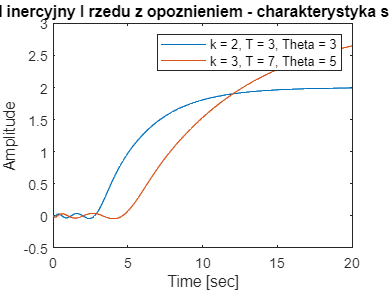


%Uklad inercyjny I rzedu z opoznieninem
[licz_op, mian_op] = pade(Theta, 5);
licz_iner = [0,k];
mian_iner = [T,1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);

inercyjny_I_op = tf(licz, mian);

y6 = step(inercyjny_I_op, t);
y6_i = impulse(inercyjny_I_op, t);

Theta_b = 5;

[licz_op_b, mian_op_b] = pade(Theta_b, 5);
licz_iner_b = [0,k_b];
mian_iner_b = [T_b,1];
[licz_b, mian_b] = series(licz_op_b, mian_op_b, licz_iner_b, mian_iner_b);

inercyjny_I_op_b = tf(licz_b, mian_b);

y6_b = step(inercyjny_I_op_b, t);
y6_i_b = impulse(inercyjny_I_op_b, t);

figure
plot(t, y6, t, y6_b)
title('Uklad inercyjny I rzedu z opoznieniem - charakterystyka skokowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3, Theta = 3', 'k = 3, T = 7, Theta = 5')

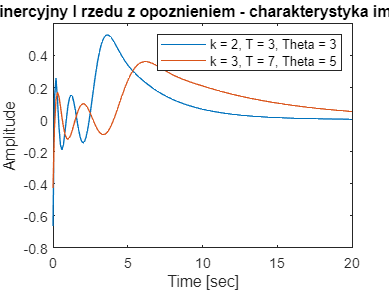

plot(t, y6_i, t, y6_i_b)
title('Uklad inercyjny I rzedu z opoznieniem - charakterystyka impulsowa')
xlabel('Time [sec]')
ylabel('Amplitude')
legend('k = 2, T = 3, Theta = 3', 'k = 3, T = 7, Theta = 5')

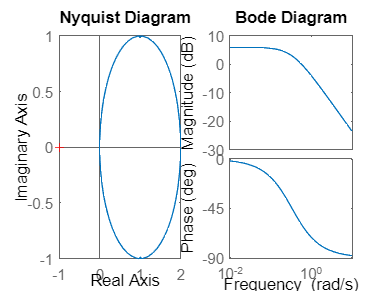

%Wykres Bodego i Nyquista
figure
subplot(2, 2, [2 4]);
bode(inercyjny_I);

subplot(2, 2, [1 3]);
nyquist(inercyjny_I);

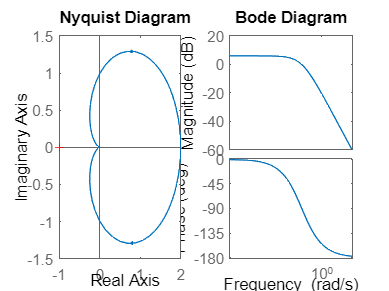

%Wykres Bodego i Nyquista
figure
subplot(2, 2, [2 4]);
bode(inercyjny_II);

subplot(2, 2, [1 3]);
nyquist(inercyjny_II);

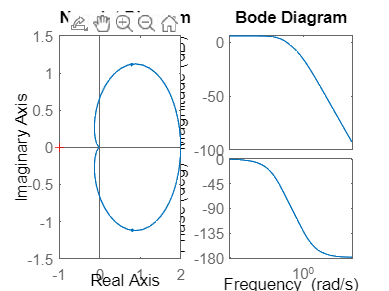

%Wykres Bodego i Nyquista
figure
subplot(2, 2, [2 4]);
bode(inercyjny_II_inny);

subplot(2, 2, [1 3]);
nyquist(inercyjny_II_inny);

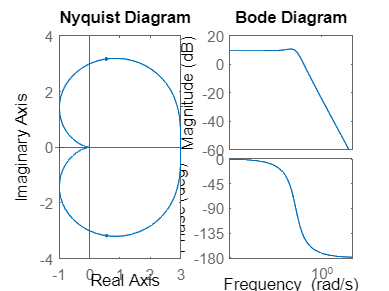


figure
subplot(2, 2, [2 4]);
bode(inercyjny_II_inny_b);

subplot(2, 2, [1 3]);
nyquist(inercyjny_II_inny_b);

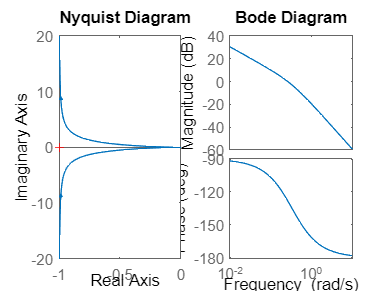

%Wykres Bodego i Nyquista
figure
subplot(2, 2, [2 4]);
bode(calkujacy_r);

subplot(2, 2, [1 3]);
nyquist(calkujacy_r);

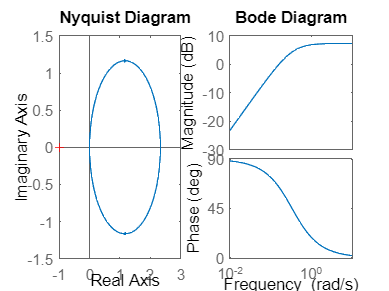

%Wykres Bodego i Nyquista
figure
subplot(2, 2, [2 4]);
bode(rozniczkujacy_r);

subplot(2, 2, [1 3]);
nyquist(rozniczkujacy_r);

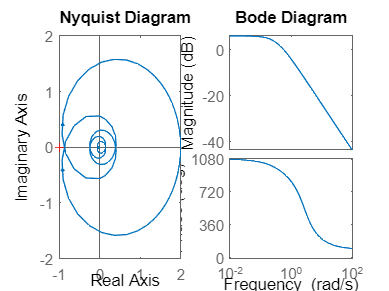

figure
subplot(2, 2, [2 4]);
bode(inercyjny_I_op);

subplot(2, 2, [1 3]);
nyquist(inercyjny_I_op);